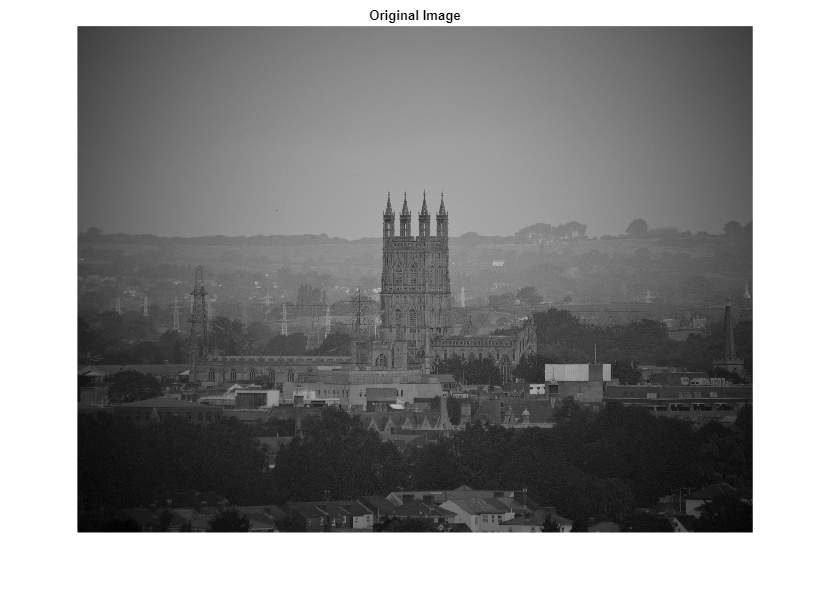

 
[fname, fpath] = uigetfile( ...
    {'*.jpg;*.jpeg;*.png'}, ...
    'Select file to open' ...
);
im = imread([fpath, fname]);
figure;
axis off;
imshow(im);
title("Original Image");

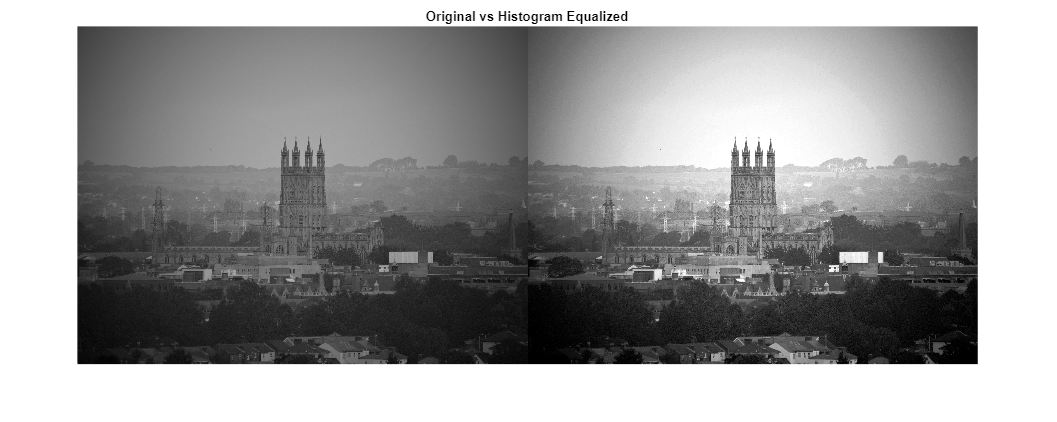

im2 = im;
if size(im, 3) == 1
    im2 = histeq(im);
else
    for c = 1:3
        im2(:, :, c) = histeq(im(:, :, c));
    end
end
figure;
axis off;
imshowpair(im, im2, 'montage');
title("Original vs Histogram Equalized");

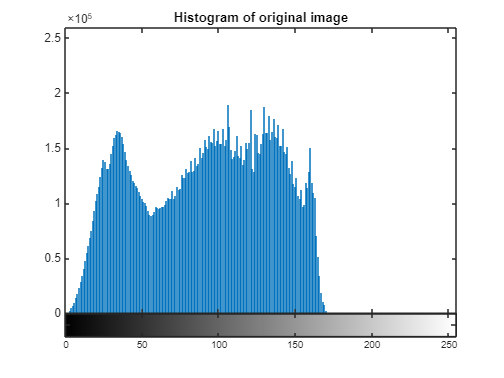

figure;
axis off;
imhist(im, 256);
title("Histogram of original image");

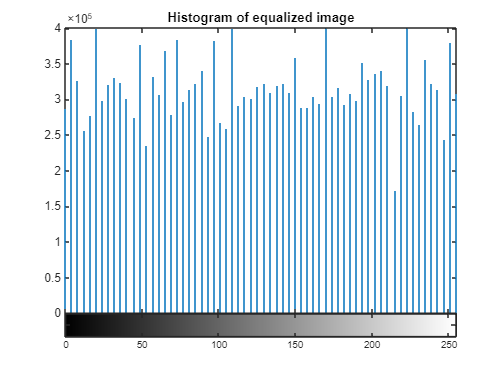

figure;
axis off;
imhist(im2, 256);
title("Histogram of equalized image");